# Explore:   Single Tower with **Stationary** Ground 

Let's explore a single floor tower with a Stationary ground ... and with a Horizontal force applied to the FLOOR

## 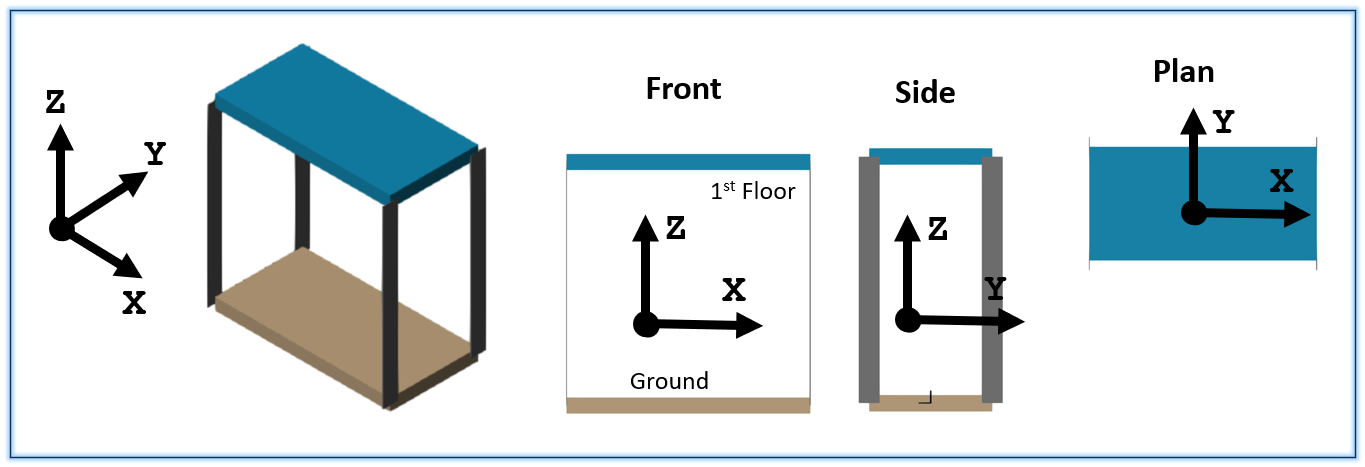

## Consult Parameter database

Consult database for parameters 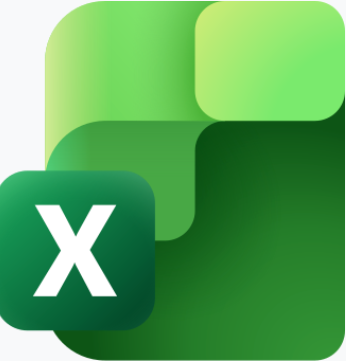 :

- See:   [`bh_flex_tower_params_CLS.m`](matlab:  open  bh_flex_tower_params_CLS.m)

- See:   [`bh_flex_tower_params_database.xlsx`](matlab:  winopen bh_flex_tower_params_database.xlsx)

params_dB = bh_flex_tower_params_CLS("bh_flex_tower_params_database.xlsx", "DEFAULT");

## Define the columns

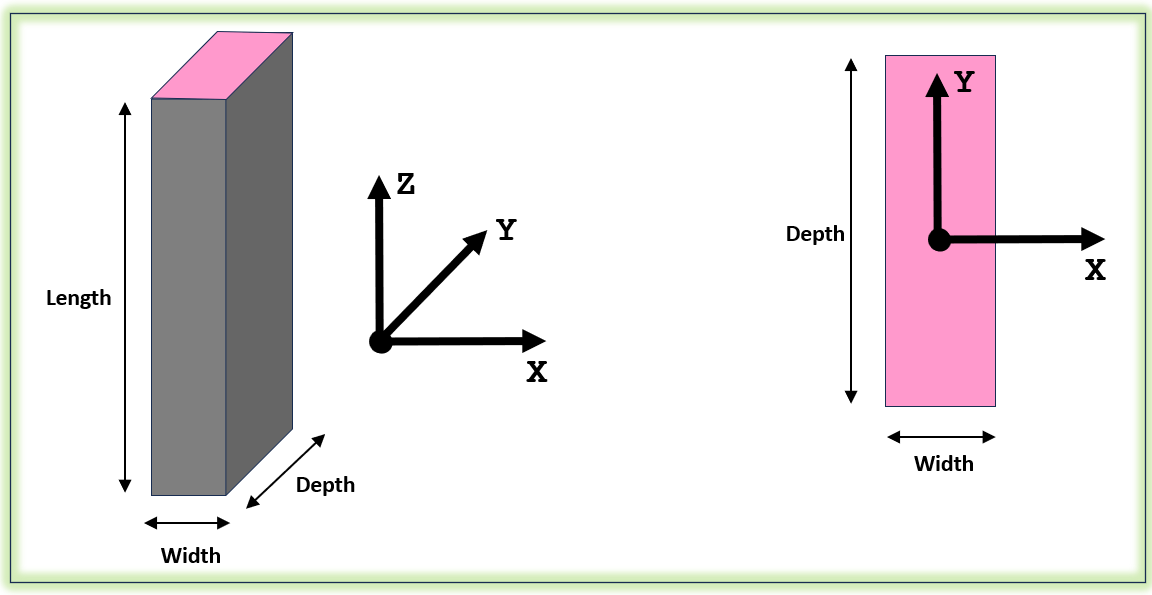

See the code files:

- [`bh_create_column_OBJ`](matlab:  open  bh_create_column_OBJ)

- [`bh_flex_column_CLS`](matlab:  open  bh_flex_column_CLS)

col_OBJ  = bh_create_column_OBJ( Width=params_dB.col_width_x, ...
                                 Depth=params_dB.col_depth_y, ...
                                 Length=params_dB.col_length_z, ...
                                 density=params_dB.col_density, ...
                                 E_GPa_Young=params_dB.col_E_Gpa, ...
                                 v_Poisson=params_dB.col_Poisson);

col_OBJ.num_eles      = params_dB.col_num_eles;

So what've we got

% col_OBJ

## Define the floors

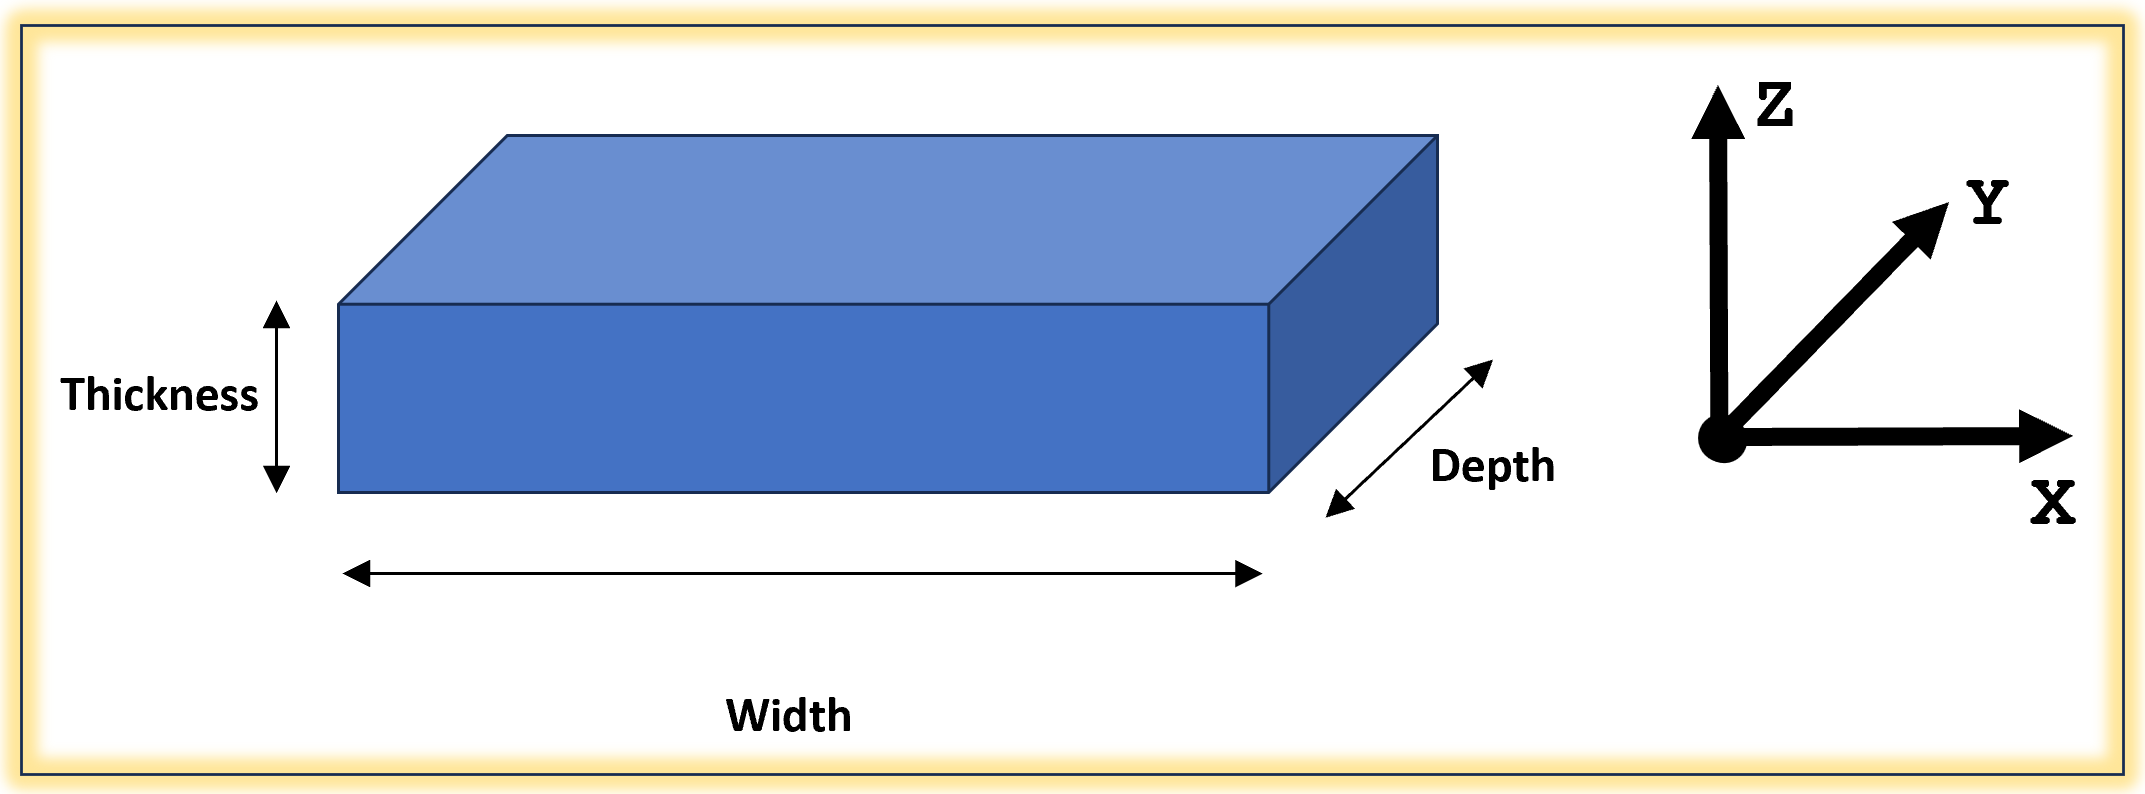

floor_OBJ = bh_create_floor_OBJ( Width=params_dB.floor_width_x, ...
                                 Depth=params_dB.floor_depth_y, ...
                                 Thickness=params_dB.floor_thick_z, ...
                                 Mass=params_dB.floor_mass );

## Define parameters for the checkered looking Earth ground

earth_vis_OBJ = earth_vis_CLS();
earth_vis_OBJ.tile_L = 0.1;  % (m)